# Example 6.15: System Identification for CO2 (Data)

Note: this script creates the data of Example 6.15 (Section 6.3.3) of **Statistics for Chemical Engineers**: the CO2 response of a room to a rectangular input. system identification example victor m zavala, uw-madison, 2024

clc; clear all; close all hidden;

Fs = 1;               % Sampling frequency (rad/min)
T = 1/Fs;             % Sampling period (min)
L = 24*60/T;          % Length of signal (1 day)
t = (0:L-1)*T';       % Time vector (sec)
rng(0);

## Input signal

step duration (min)

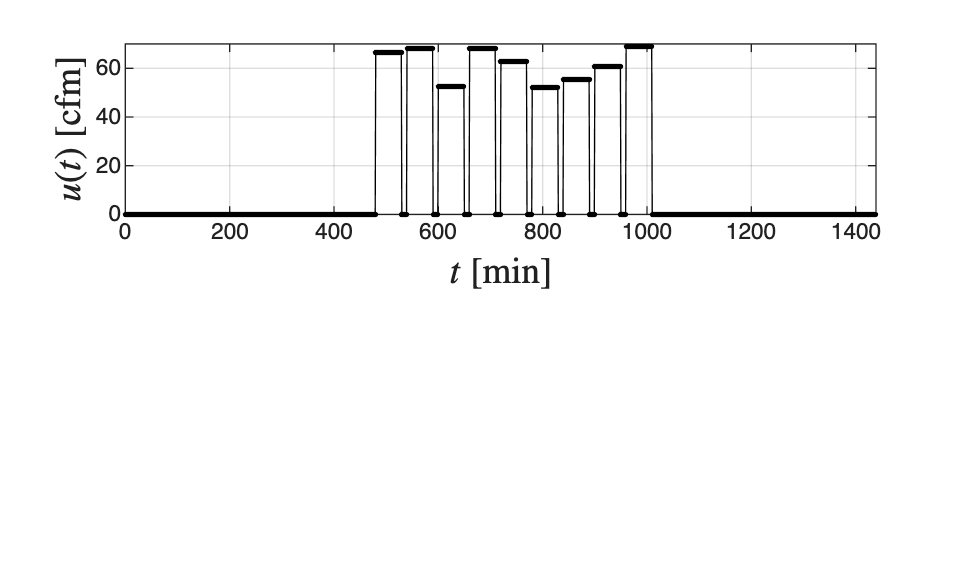

stepdur = 50;
 tpulse = (0:(60-1))*T';
         
% get rectangular response
upulse = rectpuls(tpulse,stepdur*2);
u =[];
for k = 1:8
u = [u 0*upulse];
end
for k = 9:17
u = [u (50+20*rand)*upulse];
end
for k = 18:24
u = [u 0*upulse];
end
u = u(:);

% visualize input signal
figure(1)
subplot(2,1,1)
plot(t,u,'black.-')
hold on
xlabel('$t$ [min]','Interpreter','latex','FontSize',14)
ylabel('$u(t)$ [cfm]','Interpreter','latex','FontSize',14)
grid on
axis([0 max(t) 0 70])


 co2init = 400;          % initial conditions 
       G = 1.1e4;        %  ppm-cf/min  (co2 generation per occupant)
       V = 10000;        %  cf  (building volume)
    camb = 400;          % ppmV (fresh air co2 concentration)
     noc = 0;            % number of occupants
       q = 15*66;        % cfm  (air flow), ashrae standard 8 cfm/occupant
     co2 = camb;         % co2 at stedy-state
 

## Simulated response

simulate reference system with Laplace

K=G/q;
tau=V/q;

% set real dynamic system
 num = [K];
 dem = [tau 1];
 sys_real = tf(num,dem)

sys_real =     11.11
  ----------
  10.1 s + 1
 
Continuous-time transfer function.


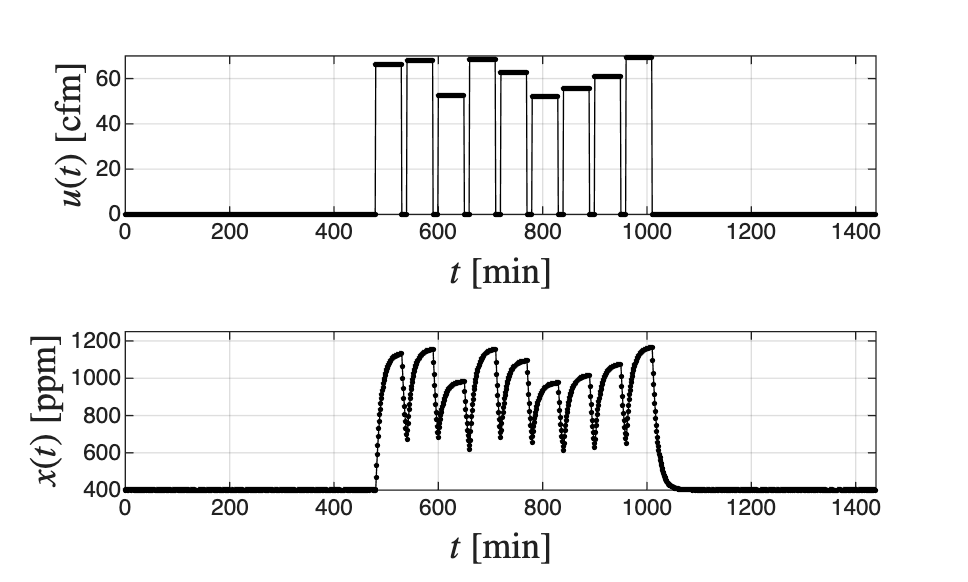

 
% simulate system with input
[x,t]=lsim(sys_real,u,t);
x = x(:);
x = x + rand(L,1);
x = x + camb;

subplot(2,1,2)
plot(t,x,'black.-')
hold on
xlabel('$t$ \textrm{[min]}','Interpreter','latex','FontSize',14)
ylabel('$x(t)$ \textrm{[ppm]}','Interpreter','latex','FontSize',14)
grid on
axis([0 max(t) 400 1250])
print -depsc ch6_sysid_data.eps


data = [t u x];
save 'Data/data_sysid_co2.dat' data -ascii

   

## Note

The estimation itself is in ch6_sysid_co2_est.